# Invariant Transformation PCA

## What is it?

The method based on PCA (Principal Component Analysis) proposed by Kim generates a space invariant to the illumination to reduce the effect of shadows and variations in light intensity. The algorithm searches for the optimal projection in the logarithmic-chromatic space to minimize the variability caused by illumination.

## Basic operation of the transformation

**1. RGB spectral model:**

The spectral response of a specific channel $\rho_k$ (with  𝑘={𝑟,𝑔,𝑏}) is defined as:


$$\rho_k = \sigma \int E(\lambda) S(\lambda) Q_k(\lambda) d\lambda$$


where:

- $\sigma$: constant factor denoting Lambert shading.

- $E(\lambda)$: incident illumination on the perceived surface element.

- $S(\lambda)$: spectral reflectance of the surface.

- $Q(\lambda)$: $k$ channel spectral sensitivity.

- $\lambda$: wavelength.

**2. Logarithmic transformation:**

The algorithm converts the model to a logarithmic space to minimize the effect of illumination. The following logarithmic ratios are calculated:


$$r = \log \frac{R}{(RGB)^{1/3}}, \quad b = \log \frac{B}{(RGB)^{1/3}}
$$


where:

- $(RGB)^{1/3}$: geometric mean of the three channels.

**3. Projection based on PCA:**

The values are projected into a logarithmic-chromatic space, where the optimal direction is found using PCA:


$$I_{\theta} = r \cos \theta + b \sin \theta
$$


his is achieved by applying Principal Component Analysis to the calculated values.

## Implementation analysis:

**1. Input parameters:**

- $image$: image in RGB format.

**2. Image adjustment to avoid negative logarithms:**

Add 1 to all pixels to avoid negative values in logarithmic calculations.

image = image + 1;

**3.  Random pixel sampling:**

A random sample of 1% of the pixels is taken to calculate the projection direction.

[h, w, ~] = size(image);
sample_size = ceil(h * w / 100);
sampled_pixels = zeros(3, sample_size);

% Random pixel sampling
for z = 1:sample_size
    x = randi(w);   y = randi(h);
    sampled_pixels(:, z) = reshape(image(y, x, :), [3 1]);
end

img_R = sampled_pixels(1, :);
img_G = sampled_pixels(2, :);
img_B = sampled_pixels(3, :);

geoM = (img_R .* img_G .* img_B).^(1/3);

**4. Calculation of logarithmic chromaticity:**

The logarithmic ratios are calculated to create the logarithmic-chromatic space.

x1 = log(img_R ./ geoM); % R/G
x2 = log(img_B ./ geoM); % B/G

**5. Principal component analysis:**

Principal component analysis (PCA) is used to find the direction of projection.

X = [x1; x2]';
[~, ~, V] = svd(X, 'econ');
alpha = abs(atand(-V(1) / V(2)));

**6. Generate the invariant image based on PCA:**

The calculated values are projected in the optimal direction determined by PCA.

img_R = double(image(:,:,1));
img_G = double(image(:,:,2));
img_B = double(image(:,:,3));

geoM = (img_R .* img_G .* img_B).^(1/3);

ch_r = log(img_R ./ geoM);
ch_b = log(img_B ./ geoM);
rad_t = pi * (alpha - 1) / 180;
grayImg = ch_r * cos(rad_t) + ch_b * sin(rad_t);

**7. Normalize the final image:**

Normalize the image values between 0 and 1.

tmp = grayImg;
tmp = tmp - min(min(tmp));
imagenFinal = tmp / max(max(tmp));

## Complete code

function [imagenFinal] = PCA(image)
    image = image + 1;
    [h, w, ~] = size(image);
    sample_size = ceil(h * w / 100);
    sampled_pixels = zeros(3, sample_size);

    % random pixel sampling : 1%
    for z = 1:sample_size
        x = randi(w);   y = randi(h);
        sampled_pixels(:, z) = reshape(image(y, x, :), [3 1]);
    end
    
    img_R = sampled_pixels(1, :);
    img_G = sampled_pixels(2, :);
    img_B = sampled_pixels(3, :);

    geoM = (img_R .* img_G .* img_B).^(1/3);

    % RG BG chromaticity
    x1 = log(img_R ./ geoM); % R/G
    x2 = log(img_B ./ geoM); % B/G
    
    % calculate pca
    X = [x1; x2]';
    [~, ~, V] = svd(X, 'econ');
    alpha = abs(atand(-V(1) / V(2)));
    
    % generate pca_ii image
    img_R = double(image(:,:,1));
    img_G = double(image(:,:,2));
    img_B = double(image(:,:,3));

    geoM = (img_R .* img_G .* img_B).^(1/3);

    ch_r = log(img_R ./ geoM);
    ch_b = log(img_B ./ geoM);
    rad_t = pi * (alpha-1) / 180;
    grayImg = ch_r * cos(rad_t) + ch_b * sin(rad_t);
    
    % normalize
    tmp = grayImg;
    tmp = tmp - min(min(tmp));
    imagenFinal = tmp / max(max(tmp));
end

An example of a program image and its corresponding transformation:

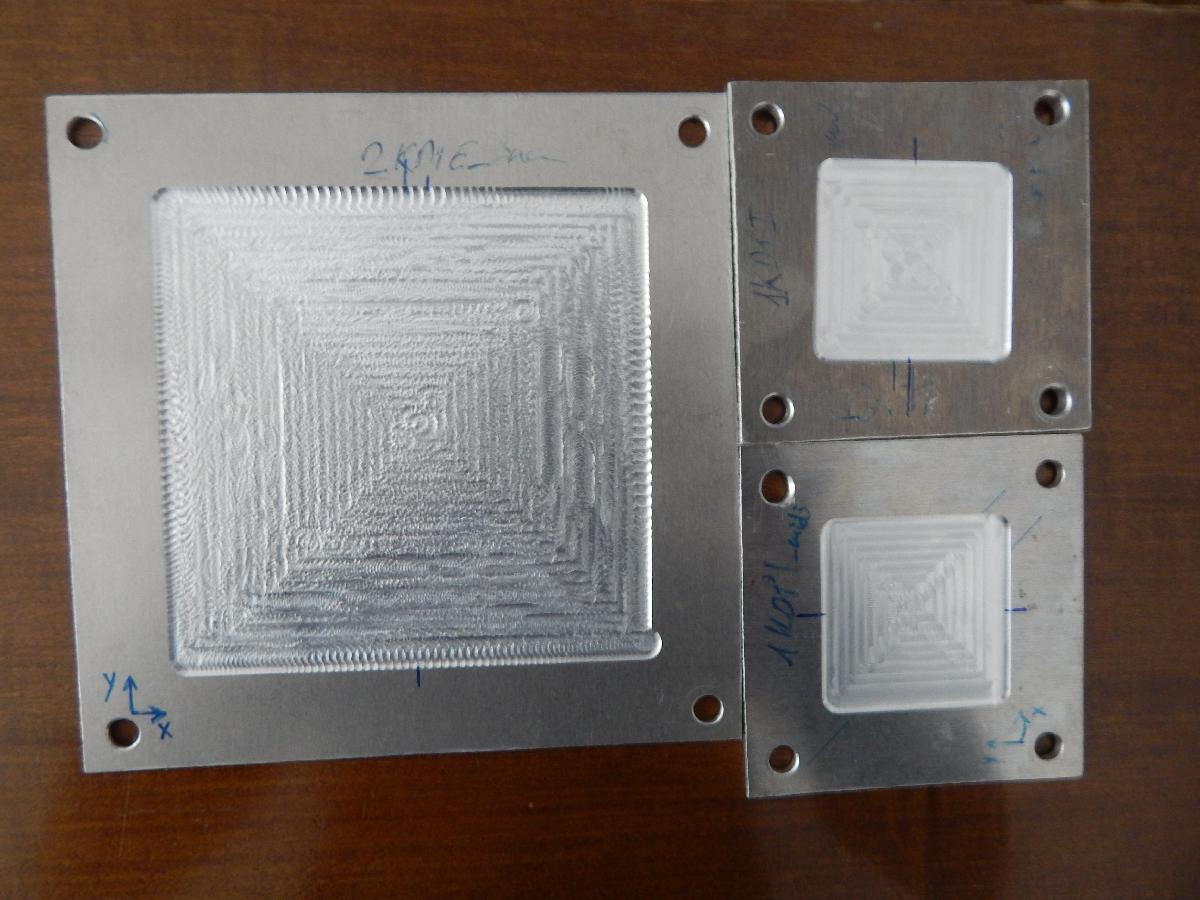    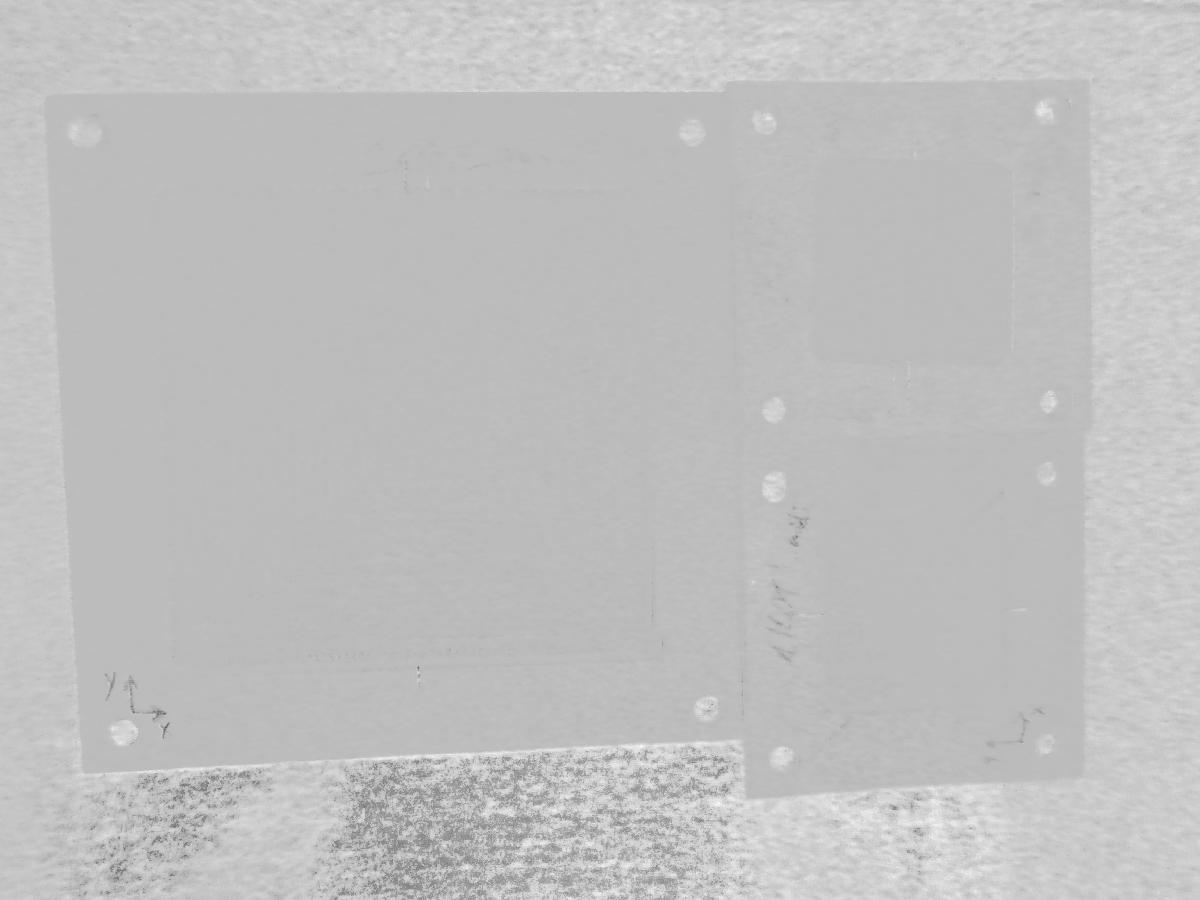

## References

- Kim, T., Tai, Y. W., & Yoon, S. E. "PCA based Computation of Illumination-Invariant Space for Road Detection," *IEEE Winter Conference on Applications of Computer Vision*, pp. 632-640, 2017.